# Midterm 2 Programming Assignment

## Tarun Kamath

## Part 1: Analyzing an intracellular recording

- By looking at the variable timeaxis in intracellular.mat we can see that the first 10417 recordings happen in 1 second. Thus the frequency is 10417 samples/s or **10417 Hz. **

- So our recording has a frequency of 10417 Hz, thus we need to plot the first 3*10417 = 31251 recordings. Our first action potential happens at 0.03 seconds so we will plot only points around that time.

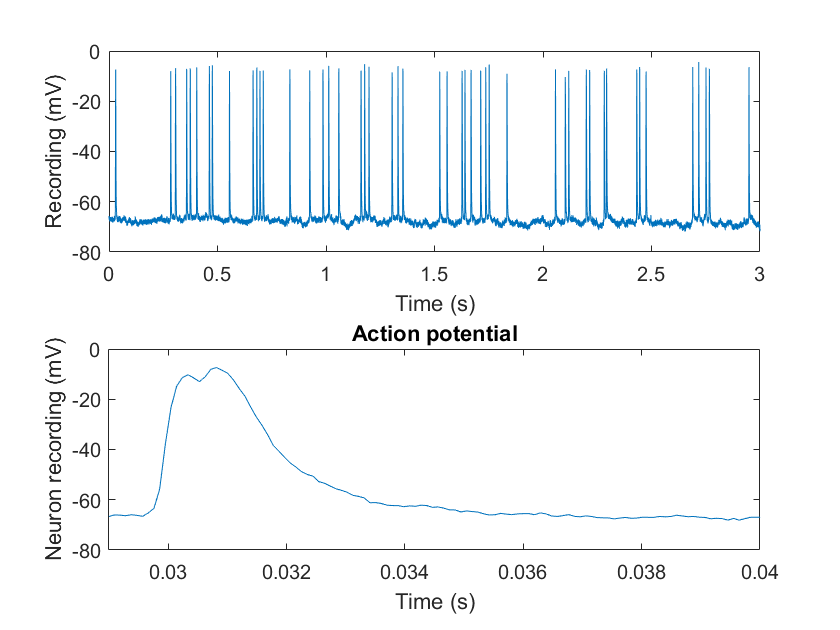

load 'intracellular.mat';
figure;
subplot(2,1,1);
plot(timeaxis,Vm);
xlim([0 3]);
xlabel('Time (s)');
ylabel('Recording (mV)');
subplot(2,1,2);
plot(timeaxis,Vm);
xlim([0.029 0.04]);
title('Action potential')
xlabel('Time (s)');
ylabel('Neuron recording (mV)');

3. By inspection of the previous graph we can see that once we pass around -60 mV, the recording likely reflects at least the beginning of the peak. To specifically chose close to the top of the action potential, we will choose a threshold of -20 mV. Looking at the variable SpikeTimes, we see the action potentials have at least around a .01 s separation. We will use this as our mindistance threshold.

Fs = 10417;
[peaks, indices] = findpeaks(Vm,'MinPeakHeight', -20, 'MinPeakDistance',10);
for i = 1:length(indices) 
    newindices(1,i) = timeaxis(indices(i));
end
[PCD,FAR] = testSpikeDetector(newindices,SpikeTimes)


Spike detector performance:
   Total actual spikes in voltage record = 2026 spikes
   Percentage Correct detection  = 100 percent
   False alarm rate = 0 spikes/sec



PCD = 100

FAR = 0

4. Our mean firing rate is the amount of times that the neuron fires in the entire time period. We see from the SpikeTimes variable that there are 2026 firings, and the recording is 151.5595 seconds long (as we see from the timeaxis variable). Thus the mean firing rate is $\frac{2026}{151\ldotp 5595}\frac{\mathrm{firings}}{\mathrm{second}}=13\ldotp 3676\text{ }\mathrm{Hz}\text{ }$

5. We can show the histogram below:

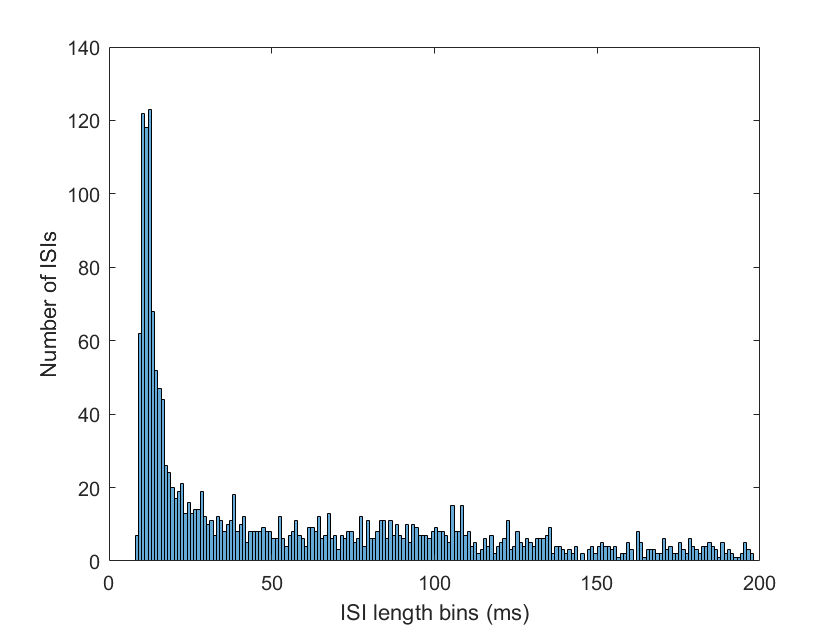

ISI = diff(SpikeTimes);
ISI_ms = 1000*ISI;
figure;
histogram(ISI_ms,'BinWidth', 1);
xlim([0 200])
xlabel('ISI length bins (ms)');
ylabel('Number of ISIs');

6. The coefficient of variation is the standard deviation of the ISI divided by the mean ISI. We can compute this below:

ISI_stdev = sqrt(var(ISI_ms));
ISI_mean = mean(ISI_ms);
CV = ISI_stdev/ISI_mean

CV = 1.0416

So our CV is 1.0416. This is not very variable. A Poisson process has a coefficient of variance equal to $\lambda^{-0\ldotp 5}$ so it is less variable than a Poisson process with $\lambda ={\left(1\ldotp 0416\right)}^2 =1\ldotp 08$.

7. We can first construct our binary train using the SpikeTimes variable and timeaxis variable.

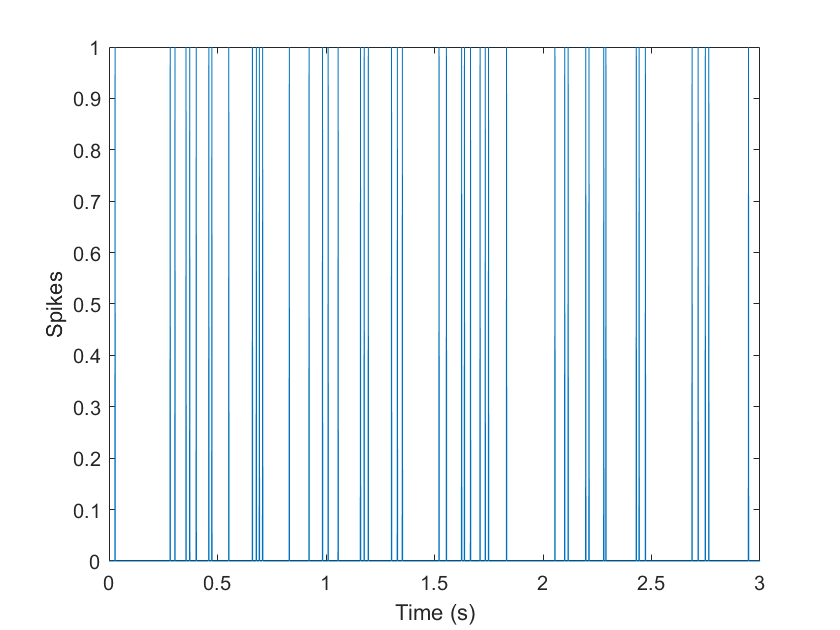

lasttimepoint = timeaxis(length(timeaxis));
endtime = round(lasttimepoint,3);
firsttime = round(timeaxis(1),3);
newtimeaxis = firsttime:.001:endtime;
spiketrain = zeros(1,length(newtimeaxis));
newtimes = zeros(1,length(SpikeTimes));
for j = 1:length(SpikeTimes)
    newtimes(1,j) = round(SpikeTimes(1,j),3);
    index = round((newtimes(1,j)*1000)-1);
    spiketrain(index) = 1;
end
figure;
plot(newtimeaxis,spiketrain);
xlim([0 3]);
xlabel('Time (s)');
ylabel('Spikes');

We can now convolve our spike train with a boxcar kernel

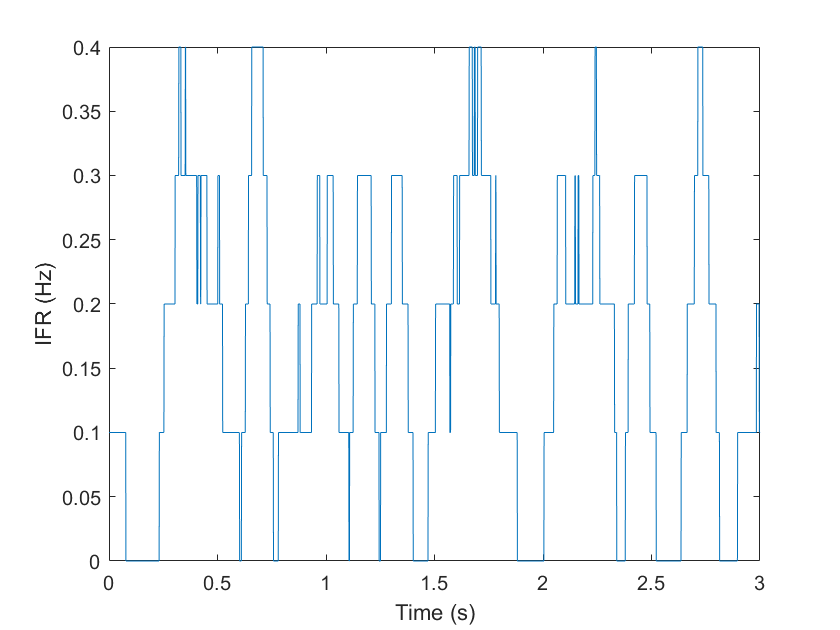

boxcarkernel = ones(1,100)/100;
IFR = conv(spiketrain,boxcarkernel,'same');
IFR_hz = IFR/0.1;
figure;
plot(newtimeaxis,IFR_hz);
xlim([0 3]);
xlabel('Time (s)');
ylabel('IFR (Hz)');

meanIFR = mean(IFR_hz)

meanIFR = 0.1337

We see that the  mean value of the IFR is **0.1337**.

8. We can use the xcorr function to get the autocorrelation of the spike train:

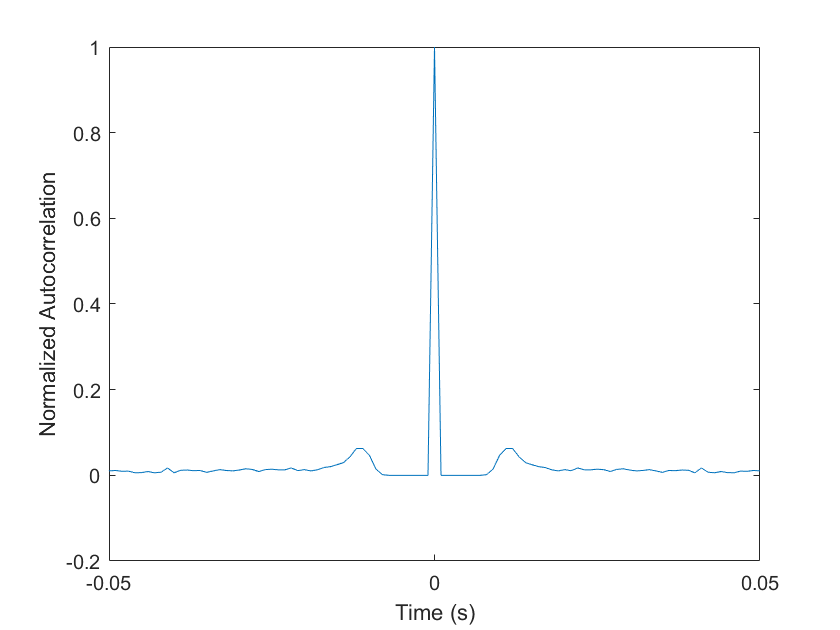

autocorr = xcorr(spiketrain);
normautocorr = autocorr/length(newtimes);
figure;
t = -endtime:.001:endtime;
plot(t,normautocorr);
xlim([-0.05 0.05]);
xlabel('Time (s)');
ylabel('Normalized Autocorrelation');

This is the normalized autocorrelation, which shows how much the function correlates with itself normalized to the spike count.

9. I would guess that the absolute refractory period is around 2-3 ms. We see there is a slight increase in the autocorrelation function at 2-3 ms from the 0 point. This would mean that there is a higher chance of a spike around 2-3 ms after the neuron fires, whereas before that (anytime less than 2 ms after a neuron fires) there is 0 chance of a neuron firing. This likely reflects the absolute refractory period, with the slight increase indicating the end of the refractory period. Thus the absolute refractory period is around **2-3 ms.**

## Part 2 : Measures of neuronal encoding 

- We can take the power spectrum of the stimulus as below

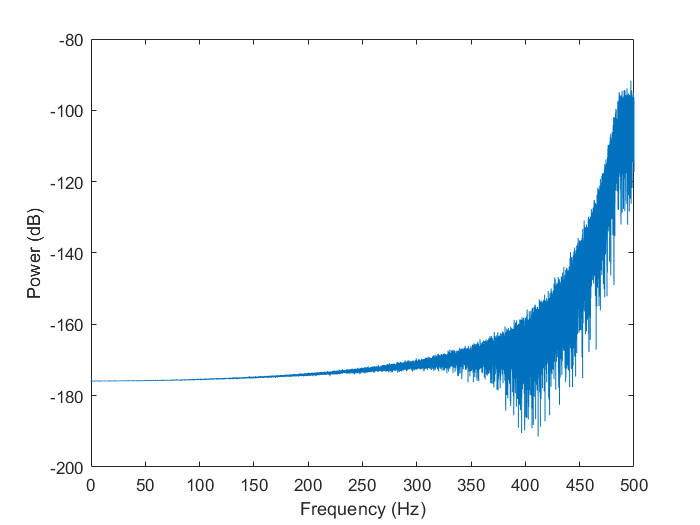

load('SpikeTrain.mat');
stimlength = length(stim);
freqstep = 1000/stimlength;
freqvec = freqstep*[-(stimlength/2):(stimlength/2)-1]; %Vector of frequencies
fftstim =fft(stim, stimlength)/stimlength; %Find FFT and normalize to length          
power = 2*abs(fftstim).^2; %Take the power
decibelpower = 10*log10(power);
figure;
plot(freqvec,decibelpower);
xlim([0 500]);
xlabel('Frequency (Hz)');
ylabel('Power (dB)');

It seems as though all of the lower frequency signal was removed from this stimulus. I this this stimulus consists fo Gaussian white noise which has been filtered with a high pass filter.

2. A raster plot shows the firing of a neuron across different trials throughout a period of time (usually triggered by a stimulus). We thus need to plot the spike times against the trial number as such:

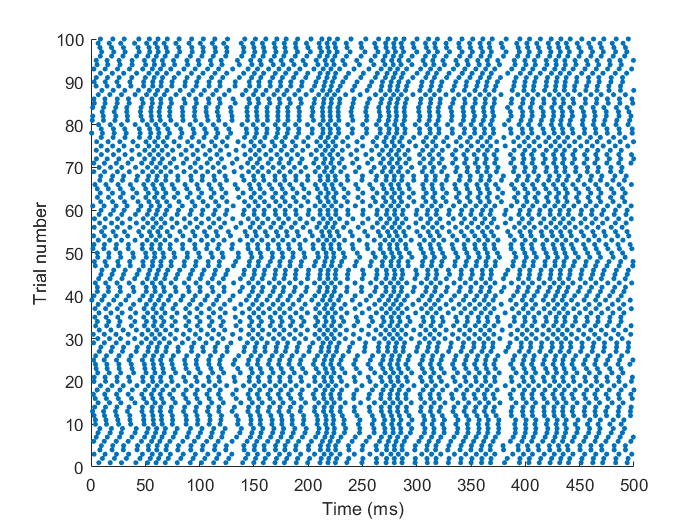

trial = data(:,1)';
spiketime = data(:,2)';
figure;
scatter(spiketime,trial,10, 'filled');
xlim([0 500]);
xlabel('Time (ms)');
ylabel('Trial number');

3. We can think of the binary spike train as an array of 1s and 0s, sampled at 2000 samples/second (2 kHz).

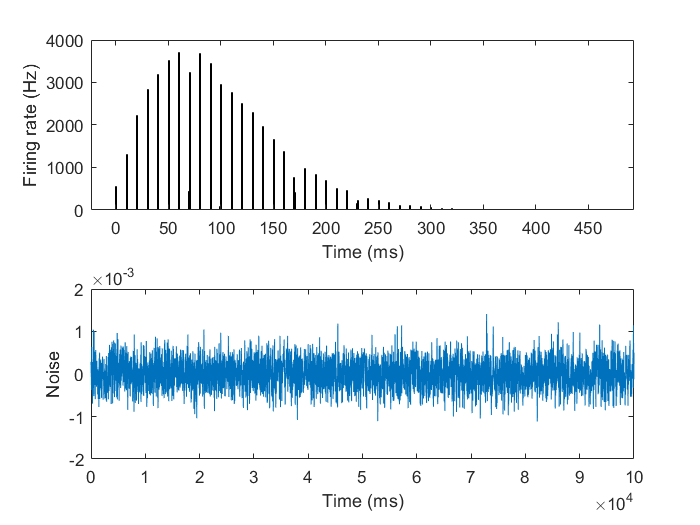

trialnumber = max(data(:,1)');
spiketrain2 = zeros(trialnumber,100000);
for k = 1:trialnumber
    I = find(trial==k);
    for n = 1:length(I)
       newtime = round(spiketime(I(n))*2)/2;
       newindex = newtime*2;
       spiketrain2(k,newindex) = 1;
    end
end
averagespikes = mean(spiketrain2);
intervals = 50000;
PSTH = zeros(1,intervals);
for m = 1:intervals
    beginningnumber = ((m-1)*2)+1; 
    finishingnumber = (2*m);
    PSTH(1,m) = (sum(averagespikes(1,beginningnumber:finishingnumber)))/(0.001);
end
time = 1:100000;
figure;
subplot(2,1,1);
histogram(PSTH, 'BinWidth', 1);
xlabel('Time (ms)');
ylabel('Firing rate (Hz)');
subplot(2,1,2);
plot(time,stim);
xlabel('Time (ms)');
ylabel('Noise');

4. We can make the cross-correlation between the spike train and the stimulus

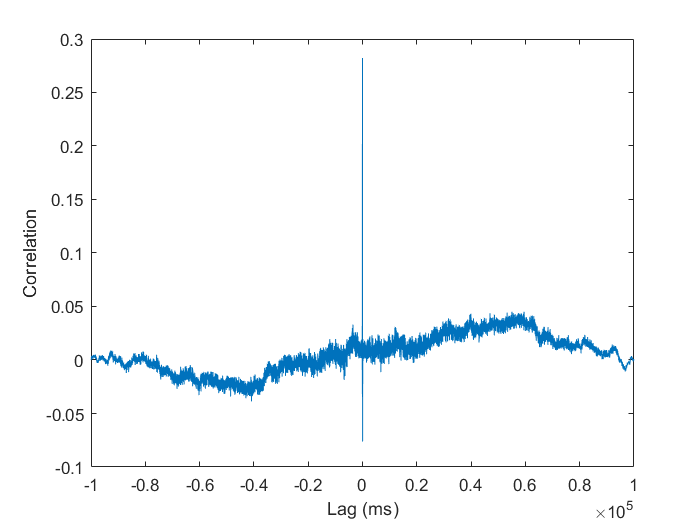

crosscorr = xcorr(spiketrain2(1,:), stim);
corrtime = -99999:1:99999;
figure;
plot(corrtime,crosscorr);
xlabel('Lag (ms)');
ylabel('Correlation');

5. The cross correlation shows how well the neuron itself responds to large changes in the stimulus, and the time between a given change in the stimulus and a correspoding action potential. This cross correlation in particular shows that a change in stimulus generates an almost instantatenous action potential, on the order of milliseconds.